g = 9.81; %m/s^2
apogee = 3393; %m
h = 250; %m Set one layer as 250m
h_main = 250; %m when the main parachute is deployed
n = apogee/h; %layer
%point of entry
x0=0;
y0=0;

%in the range of 165-230 degree in the early morning (avg 197.5)
%35-50 at noon @Cold lake mid August
wind_direction=(35.5)*ones(126,1);
curr_height = apogee;
counter=1;
x_total=0;
y_total=0;

%drogue: air resistance
%v=sqrt(2mg/density*C(coefficient)*Area)

%before the main parachute is deployed: drougue
m=57.152; %kg
d=1.225; %kg/m^2 density ?
diameter1=1.70434; %m ?
A=pi*(diameter1/2)^2; %m^2
Cd1=0.775; % ?
v_terminal1=sqrt(2*m*g/(d*Cd1*A));

%after the main parachute is deployed: main parachute
diameter2=3.048; %m 120inches ?
A=pi*(diameter2/2)^2;
Cd2=2.2; % ?
v_terminal2=sqrt(2*m*g/(d*Cd2*A));

while(n>0)
    if (curr_height >= h_main)
        %t_layer: time it takes to travel through the current layer
        t_layer=h/v_terminal1;
    else%curr_height < h_main
        t_layer=h/v_terminal2;
    end
    %update the current height to one layer down
    curr_height=curr_height - h;
    wind_profile = magnitude_calculator(curr_height); %for checking function output
    wind_xcomponent=magnitude_calculator(curr_height)*sind(wind_direction(counter));
    wind_ycomponent=magnitude_calculator(curr_height)*cosd(wind_direction(counter));
    position_x = t_layer*wind_xcomponent; %distance by wind
    position_y = t_layer*wind_ycomponent;
    x_total=x_total+position_x;
    y_total=y_total+position_y;
    counter = counter + 1;
    n=n-1;
end
xposition_final=x0+x_total; %final x coordinate
yposition_final=y0+y_total; %final y coordinate
fprintf("position_xdirection:%f\n",xposition_final(1));

position_xdirection:92.119091


fprintf("position_ydirection:%f\n",yposition_final(1));

position_ydirection:106.282822


fprintf("terminal_velocity:%f",v_terminal2);

terminal_velocity:7.551373

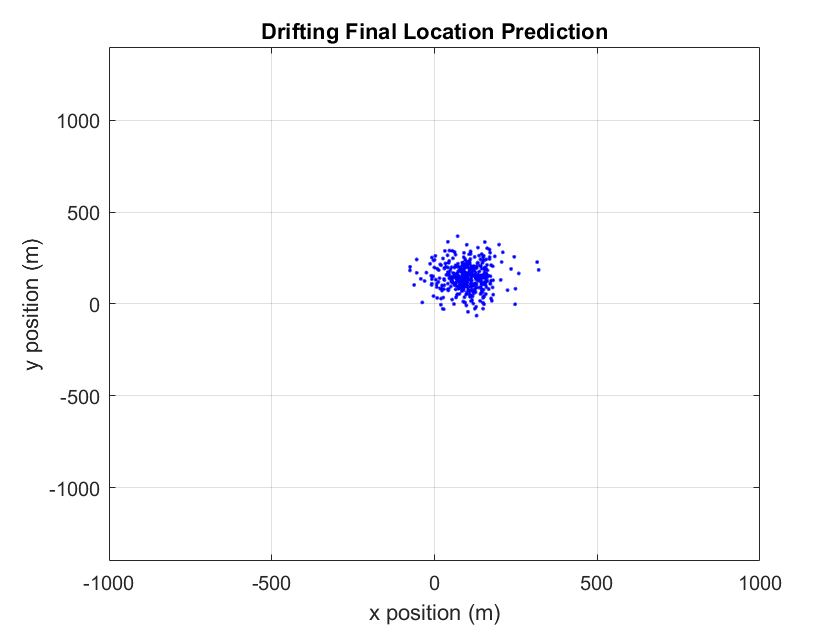


figure(1)
plot(xposition_final,yposition_final,"b.", "MarkerSize",5)
grid on
axis([-1000 1000 -1400 1400])
xlabel('x position (m)')
ylabel('y position (m)')
title('Drifting Final Location Prediction')

function vn = magnitude_calculator(x)
    varn = 1:0.01:5;    % Variance
    a = 37.55331224;
    b = 14.30107053;
    c = 6.7123204;
    v = a*exp((-(x-b)^2) / (2*(c^2)));
    vn = v + sqrt(varn).*randn(size(varn))+1; % Signal + Noise
end